# **Progetto regolatore con luogo delle radici**

#### inizializzazione dell'ambiente

clear
close all
clc

#### Definizione della funzione di trasferimento tempo continuo del processo

% parameters
Tau_meca = 0.072;
Tau_sensore = 0.014;
Tau = Tau_sensore + Tau_meca;
T = 0.115;
mu = 1;

% G_ = G not delayed
G_ = tf(mu, [T 1 0]);

% G
G = G_;
G.IODelay = Tau

G =
 
                        1
  exp(-0.086*s) * -------------
                  0.115 s^2 + s
 
Continuous-time transfer function.
Model Properties


**Definizione della funzione di trasferimento tempo discreto del processo**

%discretizzazione di G
Tc = 0.02;
G_d = c2d(G, Tc)

G_d =
 
           0.0008186 z^2 + 0.00224 z + 0.0001339
  z^(-5) * -------------------------------------
                   z^2 - 1.84 z + 0.8404
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


G_d = tf([0.0008186 0.00224 0.0001339], [1 -1.84 0.8404 0 0 0 0 0], Tc) %riscritto in forma canonica

G_d =
 
  0.0008186 z^2 + 0.00224 z + 0.0001339
  -------------------------------------
       z^7 - 1.84 z^6 + 0.8404 z^5
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


pole(G_d)

ans =          0
         0
         0
         0
         0
    0.9975
    0.8425


**Traccio luogo delle radici di G_d**

% poli e zeri di G_d
[poliG_d, zeriG_d] = pzmap(G_d)

poliG_d =          0
         0
         0
         0
         0
    0.9975
    0.8425


zeriG_d =    -2.6752
   -0.0611


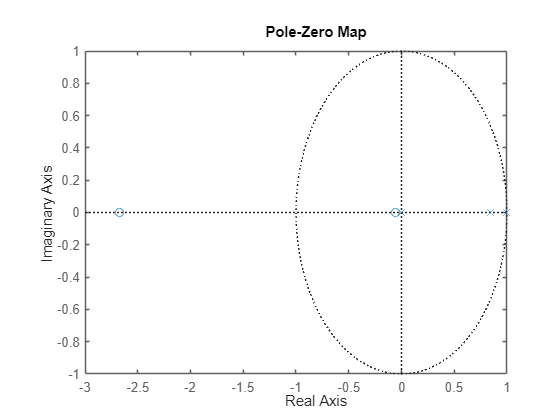

pzmap(G_d)

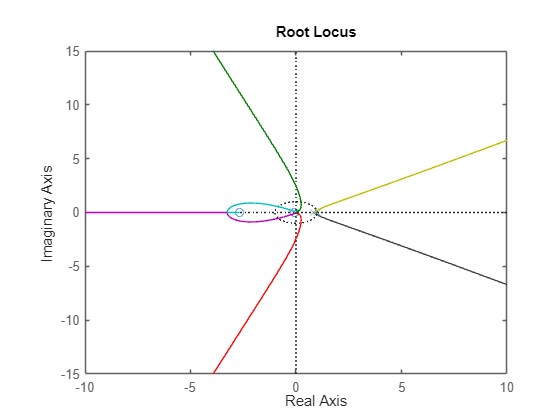


%traccio luogo
rlocus(G_d)

**Opero su luogo delle radici per trovare il regolatore**

% richieste per regolatore:

%  - asintotica stabilità del sistema ad anello chiuso
%  - astatismo a gradino 
%  - tempo assestamento < 0.5s

rltool(G_d, Tc)


**Funzioni definitive**

R = C

R =
 
  4.6129 (z-0.8425)
  -----------------
       (z-0.7)
 
Name: C
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.
Model Properties


L = R * G_d                 %open loop function

L =
 
  0.0037761 (z-0.8425) (z+2.675) (z+0.06114)
  ------------------------------------------
      z^5 (z-0.7) (z-0.8425) (z-0.9975)
 
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.
Model Properties


L_close = feedback(L, 1)    %close loop function

L_close =
 
                           0.0037761 (z+2.675) (z-0.8425) (z+0.06114)
  ---------------------------------------------------------------------------------------------
  (z-0.8424) (z+0.06107) (z^2 - 1.792z + 0.8046) (z^2 + 0.434z + 0.083) (z^2 - 0.401z + 0.1515)
 
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.
Model Properties

**Qualche test sulla funzione F**

F = L/(1+L)

F =
 
                           0.0037761 z^5 (z-0.8425) (z-0.8425) (z-0.9975) (z-0.7) (z+2.675) (z+0.06114)
  -------------------------------------------------------------------------------------------------------------------------------
  z^5 (z-0.7) (z-0.8424) (z-0.8425) (z-0.9975) (z+0.06107) (z^2 - 1.792z + 0.8046) (z^2 + 0.434z + 0.083) (z^2 - 0.401z + 0.1515)
 
Sample time: 0.02 seconds
Discrete-time zero/pole/gain model.


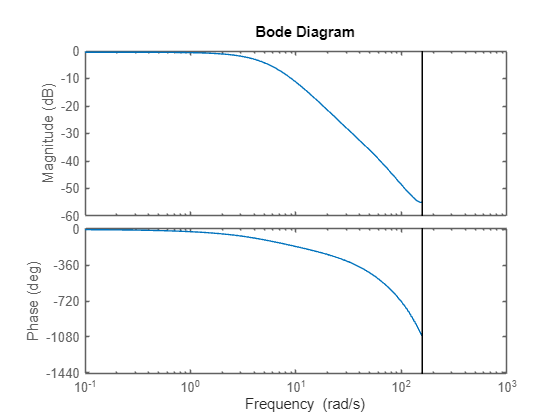


bode(F)

**Qualche test sulla funzione ad anello chiuso**

%TEST

%poles and zeros 
[poli, zeri] = pzmap(L_close)

poli =    0.8959 + 0.0444i
   0.8959 - 0.0444i
   0.8424 + 0.0000i
   0.2005 + 0.3336i
   0.2005 - 0.3336i
  -0.2170 + 0.1895i
  -0.2170 - 0.1895i
  -0.0611 + 0.0000i


zeri =    -2.6752
   -0.0611
    0.8425


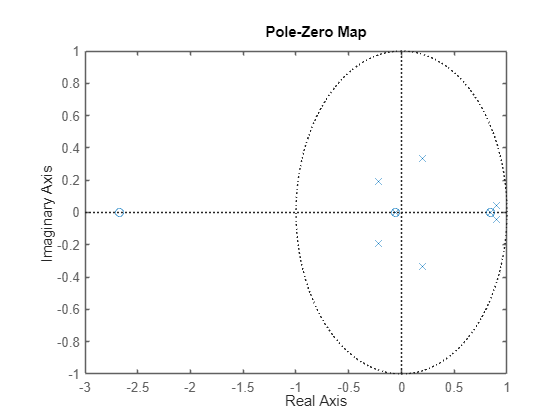

pzmap(L_close)

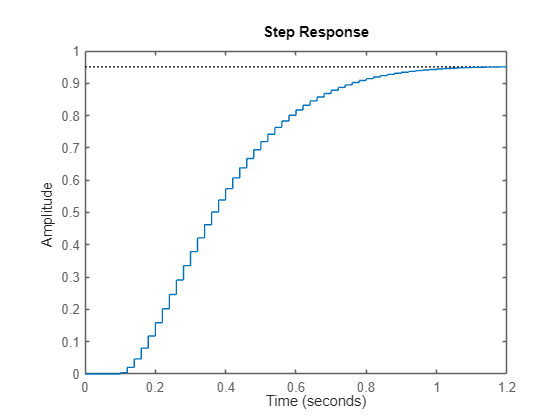



%indicial response
step(L_close)

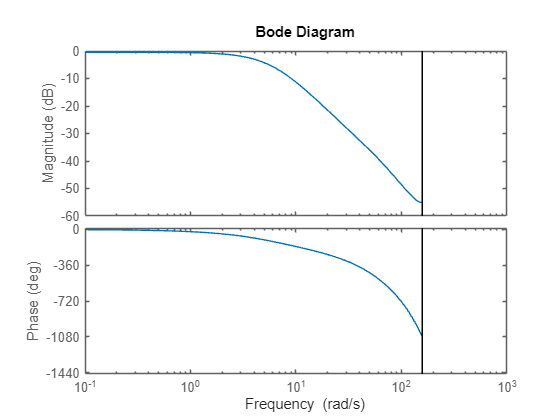



%bode diagram
bode(L_close)